map = binaryOccupancyMap;
map = binaryOccupancyMap(15,15);

x = [1];
y = [1];
setOccupancy(map, [x y], ones(5,1));
x = [2];
y = [1];
setOccupancy(map, [x y], ones(5,1));

figure;
map
show(map)


homemade_map = makemap(80);


%% Bug2
start = [25, 47];
goal = [90, 95];
imshow(homemade_map)


bug = Bug2(homemade_map);
bug.goal = goal;
bug.verbose = 1;
bug.query(start, goal, 'animate')

hold on, plot(start(1), start(2), 'r*'), text(start(1), start(2), 'START')
hold on, plot(goal(1), goal(2), 'ro'), text(goal(1), goal(2), 'GOAL')


















vel_pub = rospublisher('/cmd_vel');
velmsg = rosmessage(vel_pub);
odomSub = rossubscriber("/odom","DataFormat","struct");




r_pose = receive(odomSub)

init_position = [r_pose.pose.pose.position.x r_pose.pose.pose.position.y]
r_init_orientation = [r_pose.pose.pose.orientation.x r_pose.pose.pose.orientation.y r_pose.pose.pose.orientation.z r_pose.pose.pose.orientation.w];

eul = quat2eul(r_init_orientation);
init_orientation= eul(3);
init_pose = [init_position init_orientation]'

theta = eul(3)
theta_deg = rad2deg(theta)
rot_mat = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];

path = [0    0.00;
        1   0]

path =      0     0
     1     0


sqr_width = 1

sqr_width = 1

sqr_heigth = 1

sqr_heigth = 1


robotInitialLocation = path(1,:)

robotInitialLocation =      0     0


robotGoal = path(end,:)

robotGoal =      1     0


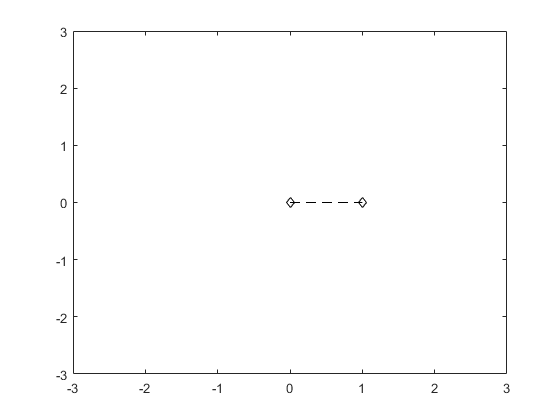


initialOrientation = 0;

robotCurrentPose = [robotInitialLocation initialOrientation]';

robot = differentialDriveKinematics("TrackWidth", 1, "VehicleInputs", "VehicleSpeedHeadingRate");

figure
plot(path(:,1), path(:,2),'k--d')
xlim([-3 3])
ylim([-3 3])


controller = controllerPurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 1.0;
controller.MaxAngularVelocity = 1;
controller.LookaheadDistance = 0.4;

goalRadius = 0.2;
distanceToGoal = norm(robotInitialLocation - robotGoal);

% TIL TURTLEBOT - DEFINITIVT!
vel_pub = rospublisher('/cmd_vel');
velmsg = rosmessage(vel_pub);
odomSub = rossubscriber("/odom","DataFormat","struct");

% Initialize the simulation loop
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
frameSize = robot.TrackWidth/0.8;
s = path(1,:)

s =      0     0


current_pose = robotCurrentPose

current_pose =      0
     0
     0



r_pose = receive(odomSub);

init_position = [r_pose.pose.pose.position.x r_pose.pose.pose.position.y]

init_position =     8.5741   -0.6402


r_init_orientation = [r_pose.pose.pose.orientation.x r_pose.pose.pose.orientation.y r_pose.pose.pose.orientation.z r_pose.pose.pose.orientation.w]

r_init_orientation =          0         0    0.0417    0.9991


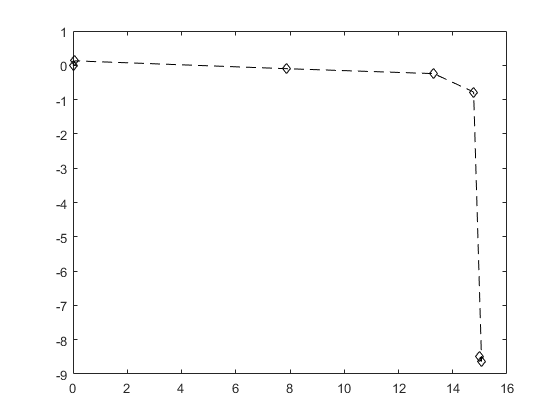


eul = quat2eul(r_init_orientation);
init_orientation = eul(3);
init_pose = [init_position init_orientation]';

theta = eul(3);
rot_mat = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];

while( distanceToGoal > goalRadius )
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    velmsg.Angular.Z = omega;	% Angular velocity (rad/s)
    velmsg.Linear.X = v;
    send(vel_pub,velmsg);

    
    % Get the robot's velocity using controller inputs
    r_pose = receive(odomSub);
    position_x = r_pose.pose.pose.position.x;
    position_y = r_pose.pose.pose.position.y;
    position = [position_x position_y];
    x = r_pose.pose.pose.orientation.x;
    y = r_pose.pose.pose.orientation.y;
    z = r_pose.pose.pose.orientation.z;
    w = r_pose.pose.pose.orientation.w;
    eul = quat2eul([x y z w]);
    orientation = eul(3);
    
    
    robotCurrentPose = [position orientation]' - init_pose;
    %vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    %robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    s(end+1,:) = robotCurrentPose(1:2);
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
    % Update the plot
    hold off
    
    % Plot path each instance so that it stays persistent while robot mesh
    % moves
  
    plot(path(:,1), path(:,2),"k--d")
    hold all
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", frameSize);
    light;
    xlim([-15 15])
    ylim([-15 15])
    
    waitfor(vizRate);
end

map = makemap(20)

makemap:
  left button, click and drag to create a rectangle
  or type the following letters in the figure window:
  p - draw polygon
  c - draw circle
  e - erase map
  u - undo last action
  q - leave editing mode


point1 =     1.0760   10.6166


point2 =    13.6106    1.0539


point1 =    14.0714   15.1647


point2 =     0.7074   20.4125


point1 =    14.5323   14.9315


point2 =    20.5230   20.1210


point1 =    20.0161   14.4650


point2 =    20.0622    0.8790


map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     1
     1     1     1     1  

map = flip(map,1)

map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0  

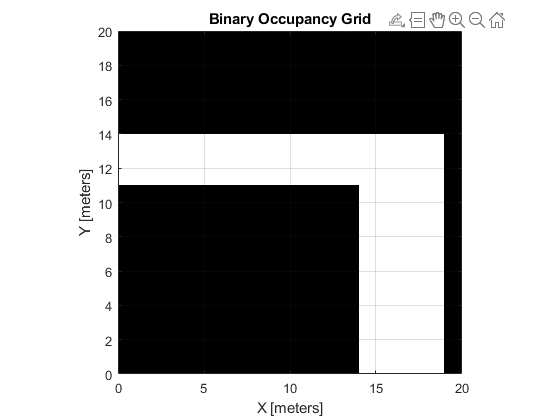

map = binaryOccupancyMap(map);
show(map)

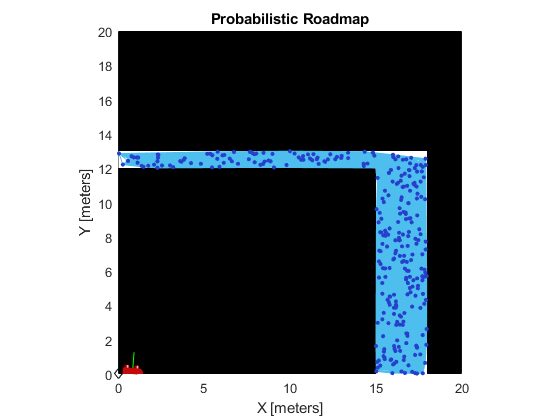


mapInflated = copy(map);
inflate(mapInflated, robot.TrackWidth/2);
prm = robotics.PRM(mapInflated);
prm.NumNodes = 300;
prm.ConnectionDistance = 10;
show(prm)


startLocation = [1 12.5];
endLocation = [16 4];
path1 = findpath(prm, startLocation, endLocation)

path1 =     1.0000   12.5000
    1.0706   12.6296
    8.8690   12.4014
   14.2953   12.2580
   15.7696   11.7209
   16.0625    3.8644
   16.0000    4.0000


path = path1 - startLocation

path =          0         0
    0.0706    0.1296
    7.8690   -0.0986
   13.2953   -0.2420
   14.7696   -0.7791
   15.0625   -8.6356
   15.0000   -8.5000


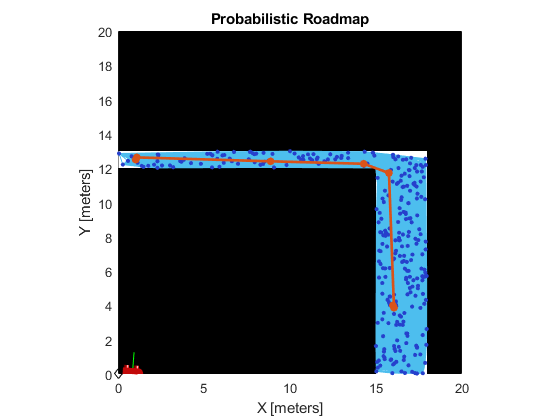

show(prm);


robotInitialLocation = path(1,:)

robotInitialLocation =      0     0


robotGoal = path(end,:)

robotGoal =    15.0000   -8.5000


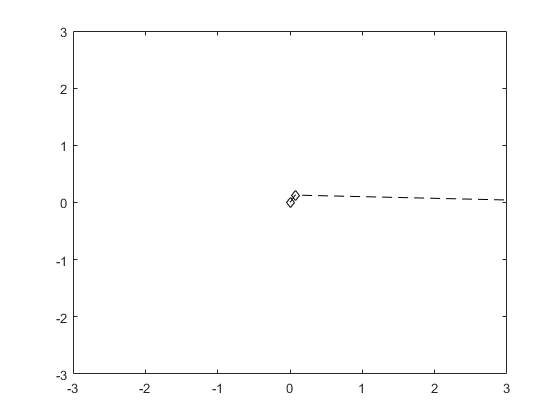


initialOrientation = 0;

robotCurrentPose = [robotInitialLocation initialOrientation]';

robot = differentialDriveKinematics("TrackWidth", 1, "VehicleInputs", "VehicleSpeedHeadingRate");

figure
plot(path(:,1), path(:,2),'k--d')
xlim([-0 15])
ylim([-0 15])


controller = controllerPurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 0.4;
controller.MaxAngularVelocity = 1;
controller.LookaheadDistance = 0.5;

goalRadius = 0.2;
distanceToGoal = norm(robotInitialLocation - robotGoal);